clear; close all;

#### Lab 7

Harrison Robel; Partner: Karen Gong

h5disp('qcd_100000_pt_1000_1200.h5')

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('higgs_100000_pt_1000_1200.h5')

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


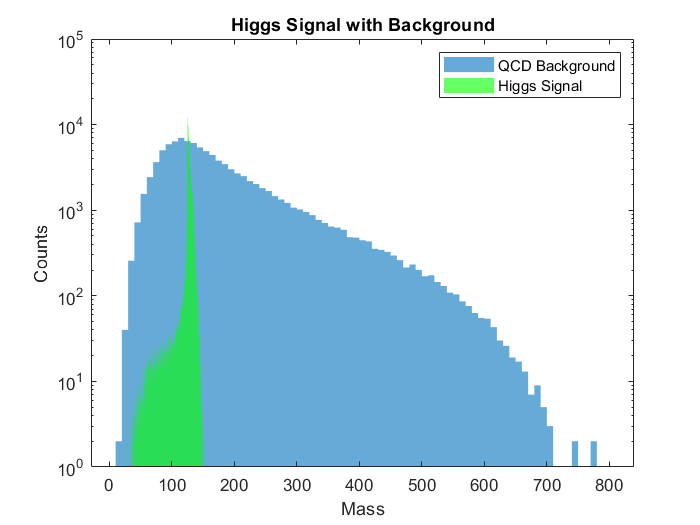

qcd = h5read('qcd_100000_pt_1000_1200.h5','/qcd_100000_pt_1000_1200');
higgs = h5read('higgs_100000_pt_1000_1200.h5','/higgs_100000_pt_1000_1200');

qcdpt = qcd(1,:);
qcdeta = qcd(2,:);
qcdphi = qcd(3,:);
qcdmass = qcd(4,:);
qcdee2 = qcd(5,:);
qcdee3 = qcd(6,:);
qcdd2 = qcd(7,:);
qcdangularity = qcd(8,:);
qcdt1 = qcd(9,:);
qcdt2 = qcd(10,:);
qcdt3 = qcd(11,:);
qcdt21 = qcd(12,:);
qcdt32 = qcd(13,:);
qcdKtDeltaR = qcd(12,:);

pt = higgs(1,:);
eta = higgs(2,:);
phi = higgs(3,:);
mass = higgs(4,:);
ee2 = higgs(5,:);
ee3 = higgs(6,:);
d2 = higgs(7,:);
angularity = higgs(8,:);
t1 = higgs(9,:);
t2 = higgs(10,:);
t3 = higgs(11,:);
t21 = higgs(12,:);
t32 = higgs(13,:);
KtDeltaR = higgs(14,:);

histogram(qcdmass,'EdgeColor','none','DisplayName','QCD Background')
set(gca,'Yscale','log')
hold on
histogram(mass,'EdgeColor','none','FaceColor','g','DisplayName','Higgs Signal')
legend("show")
hold on
xlabel('Mass')
ylabel('Counts')
title('Higgs Signal with Background')


N = 2000;
prob5 = poisscdf(2050,N);
sigma5 = norminv(prob5)

sigma5 = 1.1282


Nhiggs = 50;
Nqcd = 2000;
ratio = Nhiggs/Nqcd;

given = Nhiggs / sqrt(Nqcd);

Because there is a lot of over lap in the data we can see that without any cuts the significance is fairly low.

sorted = sort(qcdmass);

probcut1 = poisscdf(1050,1000);
sigmacut1 = norminv(probcut1)

sigmacut1 = 1.5890

probcut2 = poisscdf(1550,1500);
sigmacut2 = norminv(probcut2)

sigmacut2 = 1.3010

probcut3 = poisscdf(550,500);
sigmacut3 = norminv(probcut3)

sigmacut3 = 2.2293

probcut4 = poisscdf(250,200);
sigmacut4 = norminv(probcut4)

sigmacut4 = 3.4459

The more background that we can remove without cutting into the signal the better our significance becomes.

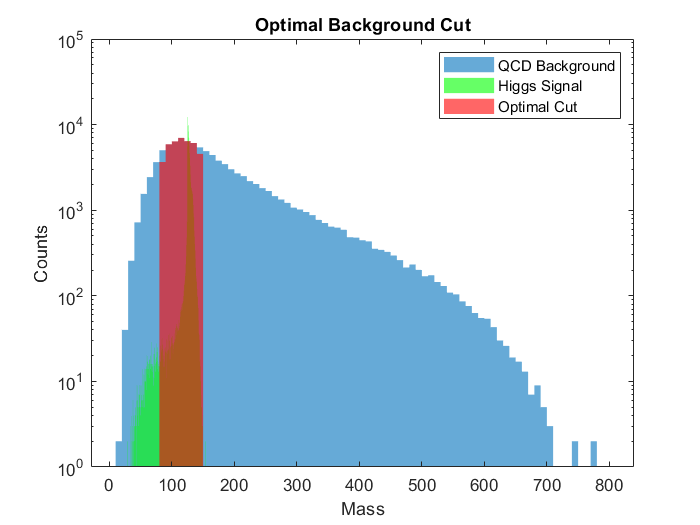

histogram(sorted(10000:50000),'FaceColor','r','EdgeColor','none','BinWidth',10,'DisplayName','Optimal Cut')
xlabel('Mass')
ylabel('Counts')
title('Optimal Background Cut')

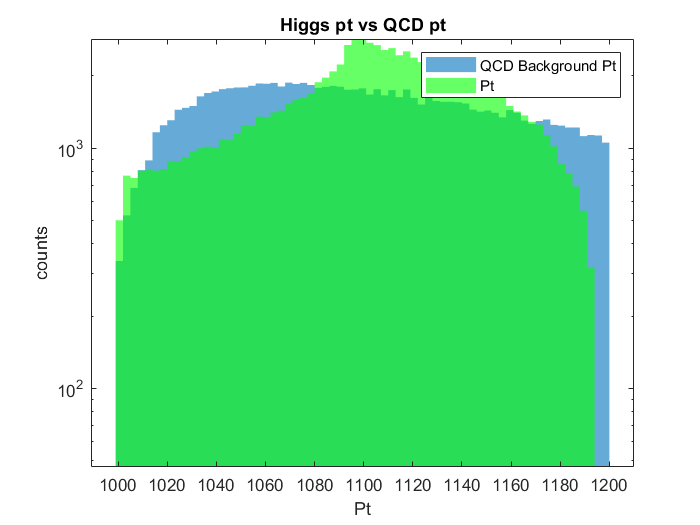

close all
histogram(qcdpt,'EdgeColor','none','DisplayName','QCD Background Pt')
set(gca,'Yscale','log')
hold on
histogram(pt,'EdgeColor','none','DisplayName','Pt','FaceColor','g')
legend('Show')
xlabel('Pt')
ylabel('counts')
title('Higgs pt vs QCD pt')
hold on

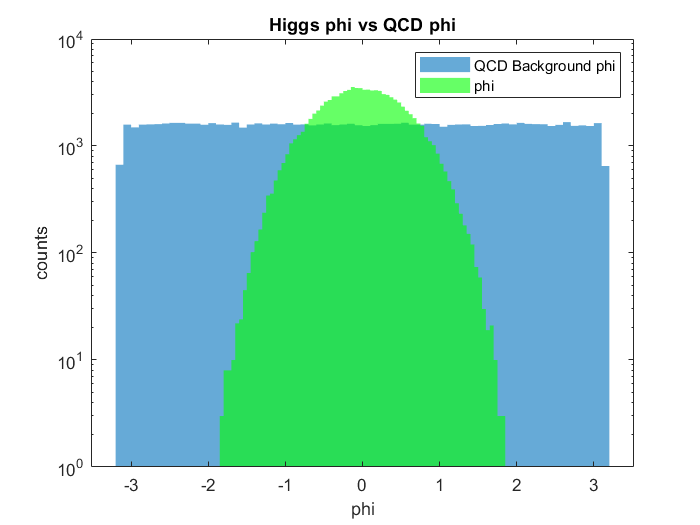

close all
histogram(qcdphi,'EdgeColor','none','DisplayName','QCD Background phi')
set(gca,'Yscale','log')
hold on
histogram(eta,'EdgeColor','none','DisplayName','phi','FaceColor','g')
legend('Show')
xlabel('phi')
ylabel('counts')
title('Higgs phi vs QCD phi')
hold on

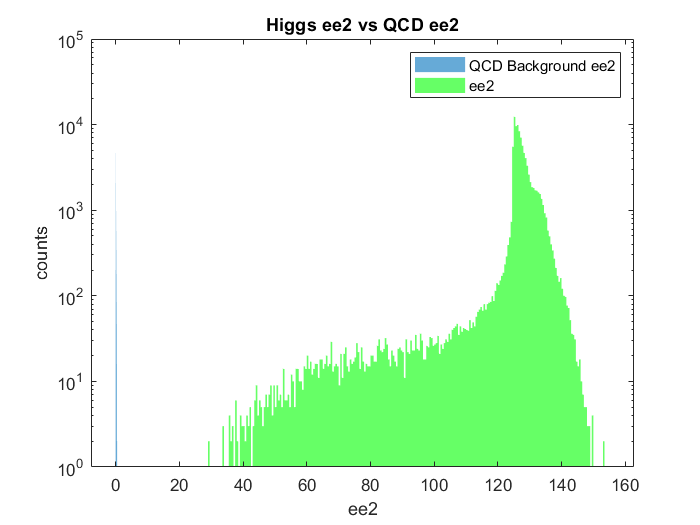

close all
histogram(qcdee2,'EdgeColor','none','DisplayName','QCD Background ee2')
set(gca,'Yscale','log')
hold on
histogram(mass,'EdgeColor','none','DisplayName','ee2','FaceColor','g')
legend('Show')
xlabel('ee2')
ylabel('counts')
title('Higgs ee2 vs QCD ee2')
hold on

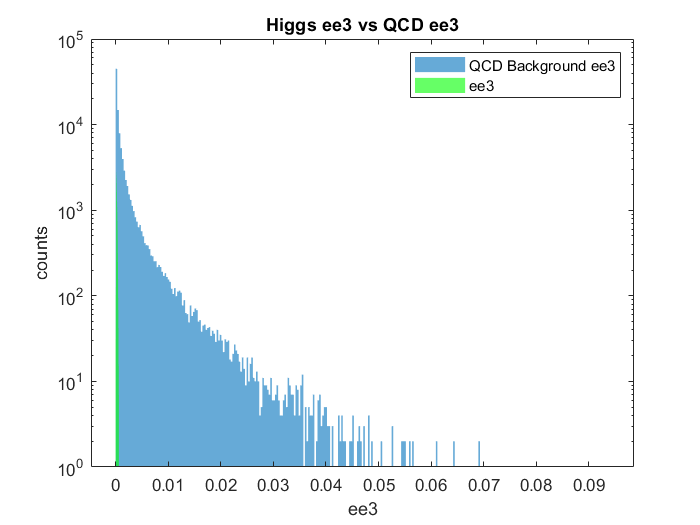

close all
histogram(qcdee3,'EdgeColor','none','DisplayName','QCD Background ee3')
set(gca,'Yscale','log')
hold on
histogram(ee3,'EdgeColor','none','DisplayName','ee3','FaceColor','g')
legend('Show')
xlabel('ee3')
ylabel('counts')
title('Higgs ee3 vs QCD ee3')
hold on

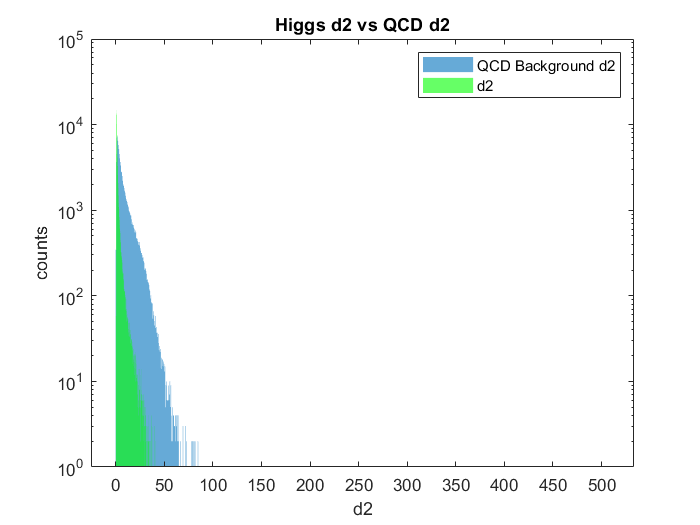

close all
histogram(qcdd2,'EdgeColor','none','DisplayName','QCD Background d2')
set(gca,'Yscale','log')
hold on
histogram(d2,'EdgeColor','none','DisplayName','d2','FaceColor','g')
legend('Show')
xlabel('d2')
ylabel('counts')
title('Higgs d2 vs QCD d2')
hold on

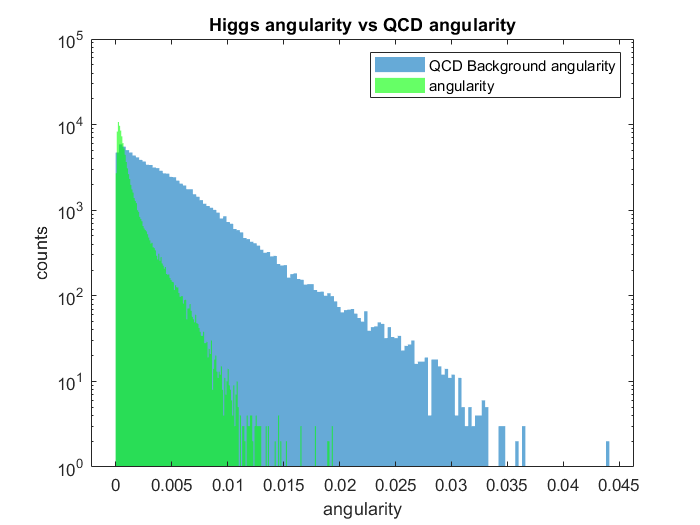

close all
histogram(qcdangularity,'EdgeColor','none','DisplayName','QCD Background angularity')
set(gca,'Yscale','log')
hold on
histogram(angularity,'EdgeColor','none','DisplayName','angularity','FaceColor','g')
legend('Show')
xlabel('angularity')
ylabel('counts')
title('Higgs angularity vs QCD angularity')
hold on

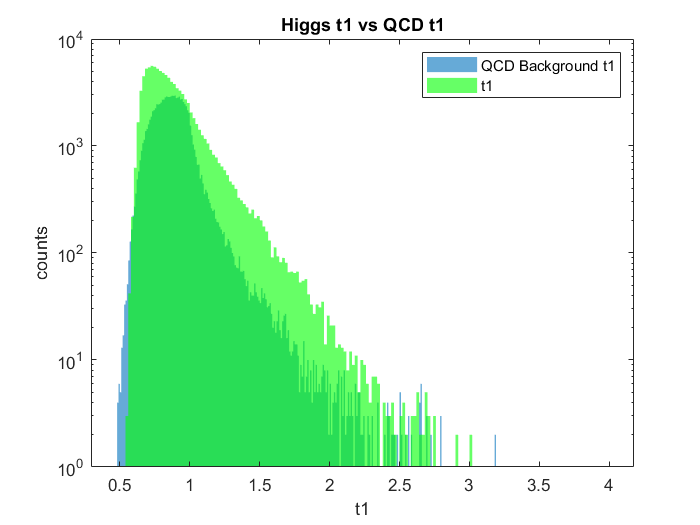

close all
histogram(qcdt1,'EdgeColor','none','DisplayName','QCD Background t1')
set(gca,'Yscale','log')
hold on
histogram(t1,'EdgeColor','none','DisplayName','t1','FaceColor','g')
legend('Show')
xlabel('t1')
ylabel('counts')
title('Higgs t1 vs QCD t1')
hold on

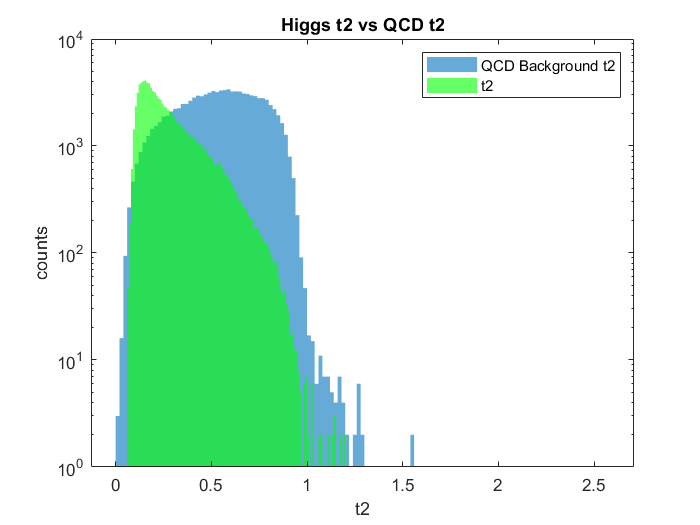

close all
histogram(qcdt2,'EdgeColor','none','DisplayName','QCD Background t2')
set(gca,'Yscale','log')
hold on
histogram(t2,'EdgeColor','none','DisplayName','t2','FaceColor','g')
legend('Show')
xlabel('t2')
ylabel('counts')
title('Higgs t2 vs QCD t2')
hold on

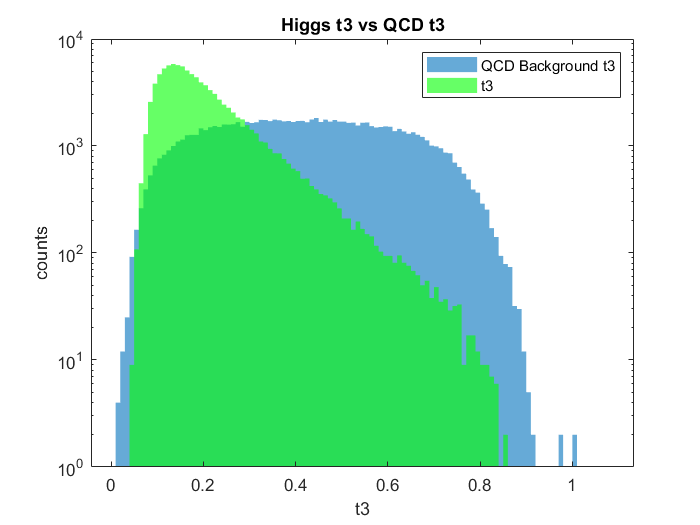

close all
histogram(qcdt3,'EdgeColor','none','DisplayName','QCD Background t3')
set(gca,'Yscale','log')
hold on
histogram(t3,'EdgeColor','none','DisplayName','t3','FaceColor','g')
legend('Show')
xlabel('t3')
ylabel('counts')
title('Higgs t3 vs QCD t3')
hold on

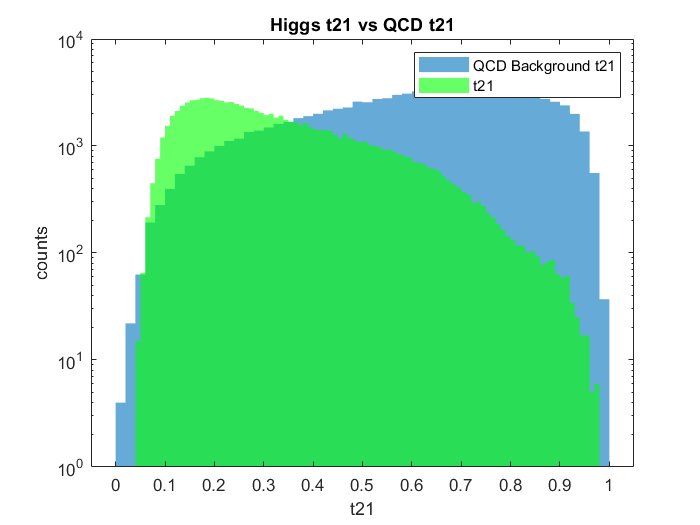

close all
histogram(qcdt21,'EdgeColor','none','DisplayName','QCD Background t21')
set(gca,'Yscale','log')
hold on
histogram(t21,'EdgeColor','none','DisplayName','t21','FaceColor','g')
legend('Show')
xlabel('t21')
ylabel('counts')
title('Higgs t21 vs QCD t21')
hold on

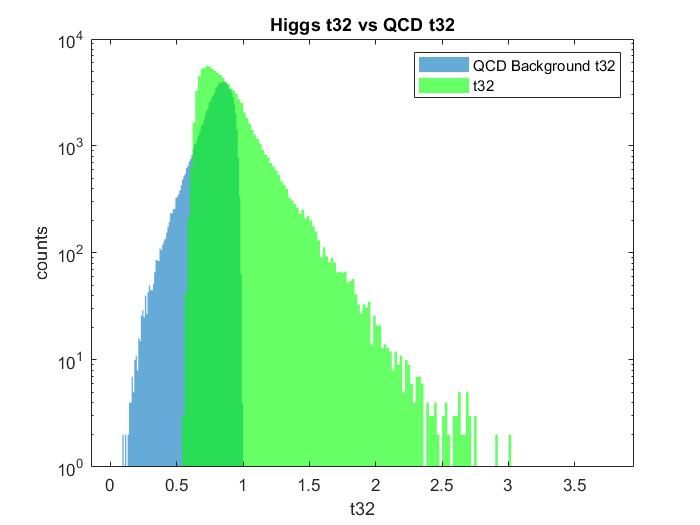

close all
histogram(qcdt32,'EdgeColor','none','DisplayName','QCD Background t32')
set(gca,'Yscale','log')
hold on
histogram(t1,'EdgeColor','none','DisplayName','t32','FaceColor','g')
legend('Show')
xlabel('t32')
ylabel('counts')
title('Higgs t32 vs QCD t32')
hold on

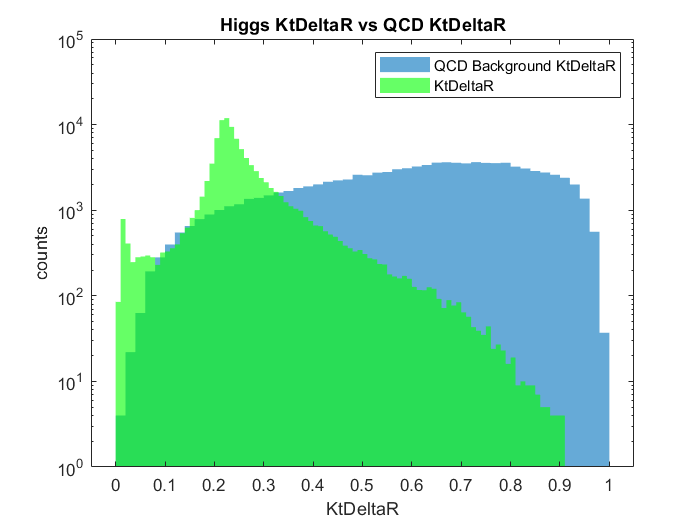

close all
histogram(qcdKtDeltaR,'EdgeColor','none','DisplayName','QCD Background KtDeltaR')
set(gca,'Yscale','log')
hold on
histogram(KtDeltaR,'EdgeColor','none','DisplayName','KtDeltaR','FaceColor','g')
legend('Show')
xlabel('KtDeltaR')
ylabel('counts')
title('Higgs KtDeltaR vs QCD KtDeltaR')
hold on

After looking at the graphs there are many graphs that have seperation between the signal and the background. The two that could have more discrimination than mass are ee2 and phi. The signal for ee2 does not occur at the same position as the background so the background does not play much of a role in the calculations.